Normalized alpha1 = 0.80737


Normalized alpha2 = 0.19263


tau1 = 4.362 ns


tau2 = 5.0418 ns


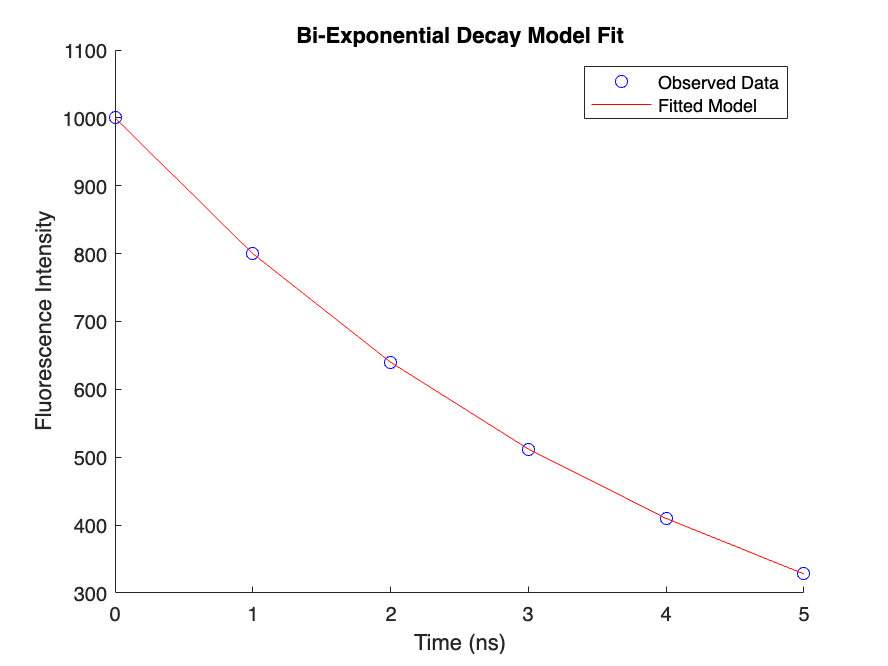

%fit bi-exponential decay model to fluorescence data

%time points (ns)
t = [0, 1, 2, 3, 4, 5];

%fluorescence intensity values
I = [1000, 800, 640, 512, 410, 328];

%bi-exponential model: I = a1*exp(-t/tau1) + a2*exp(-t/tau2)
biExpModel = @(params, t) params(1) * exp(-t / params(2)) + params(3) * exp(-t / params(4));

%initial guesses for [a1, tau1, a2, tau2]
initialGuess = [500, 2, 500, 4];

%parameter bounds
lb = [0, 0, 0, 0];
ub = [Inf, Inf, Inf, Inf];

%fit model to data using least squares
[optimizedParams, ~] = lsqcurvefit(biExpModel, initialGuess, t, I, lb, ub, options);

%extract fitted values
a1 = optimizedParams(1);
tau1 = optimizedParams(2);
a2 = optimizedParams(3);
tau2 = optimizedParams(4);

%normalize amplitudes to get pre-exponential weights
total_a = a1 + a2;
alpha1 = a1 / total_a;
alpha2 = a2 / total_a;

%print results
disp(['Normalized alpha1 = ', num2str(alpha1)]);
disp(['Normalized alpha2 = ', num2str(alpha2)]);
disp(['tau1 = ', num2str(tau1), ' ns']);
disp(['tau2 = ', num2str(tau2), ' ns']);

%plot data and fit
figure;
hold on;
plot(t, I, 'bo', 'DisplayName', 'Observed Data');
fittedCurve = biExpModel(optimizedParams, t);
plot(t, fittedCurve, 'r-', 'DisplayName', 'Fitted Model');
xlabel('Time (ns)');
ylabel('Fluorescence Intensity');
legend;
title('Bi-Exponential Decay Model Fit');
hold off;

%disable optimizer output
options = optimset('Display', 'off');